# LQR 

close all
clear
clc

Here we briefly recap LQR with and without setpoint tracking

Let's assume a static feedback architecture u = - K*x

LQR problem seeks the control law u that minimizes the cost function


$$J(u) = \sum_{k=0}^{\infty} (x^T(k)Qx(k) + u^T(k)Ru(k))$$


where:

- Q -> state weighting matrix: must be symm and positive semidef

- R -> control weighting matrix: must be symm and positive def

The optimal gain K that minimizes the control law is found from the Discrete Algebraic Riccati Equation (we don't care about since we just use lqr function)

In order to guarantee asymptotic stability, we must provide:

- complete reachability: reachability matrix rank must have full rank

- observability of the penalized states: the pair (A, Cq) must be observable, with Cq defined as Q = Cq' * Cq

## Exercise 

#### Lab 4, problem 1

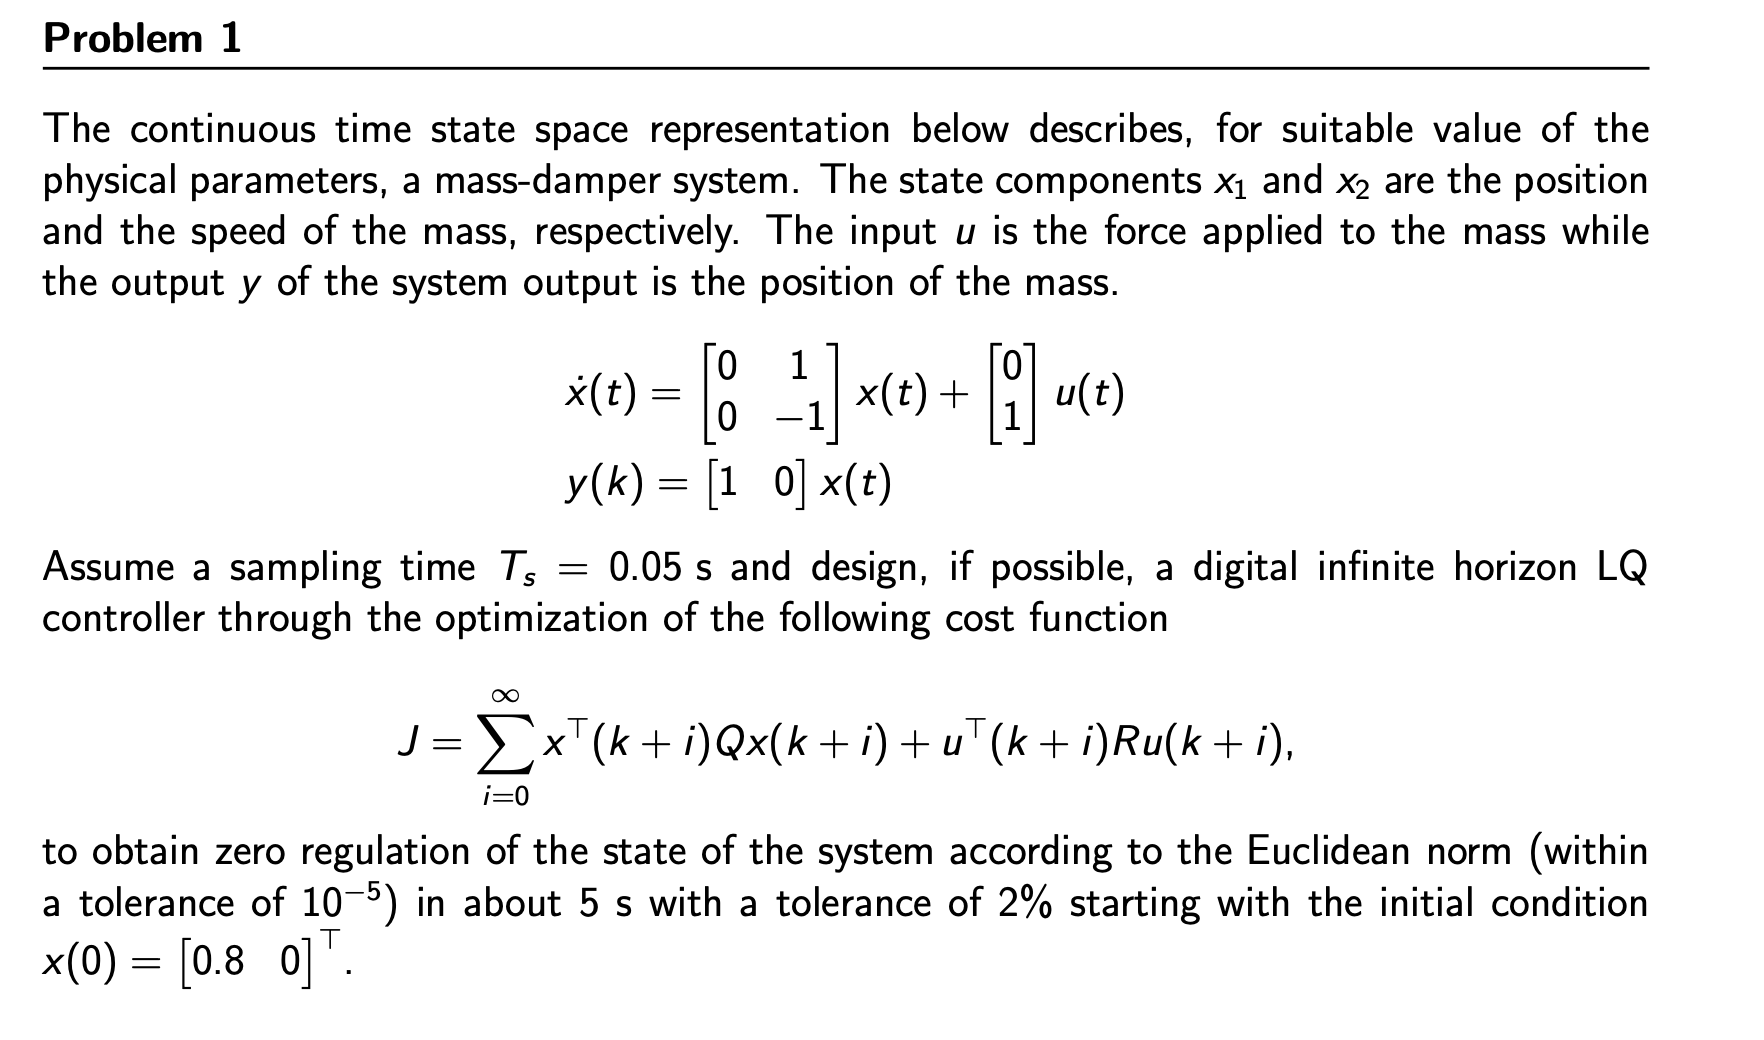

A = [0 1; 0 -1];
B = [0; 1];
C = [1 0];
x0 = [0.8; 0];
Ts = 0.05;
sys = ss(A,B,C,0);

% define DT system
sys_d = c2d(sys,Ts,'zoh');
Ad = sys_d.a;
Bd = sys_d.b;
Cd = sys_d.c;

% define weights: we start with unitary values
Q = [1 0; 0 1];
R = 1;

% check ctrb and obsv

Mr = ctrb(Ad,Bd);
rank_Mr = rank(Mr)

rank_Mr = 2


Cq = chol(Q);
Mo = obsv(Ad,Cq);
rank_Mo = rank(Mo)

rank_Mo = 2


% after checked ctrb and obvs we can solve lqr problem
K = dlqr(Ad,Bd,Q,R);

% and that's it (for now)

#### Simulation

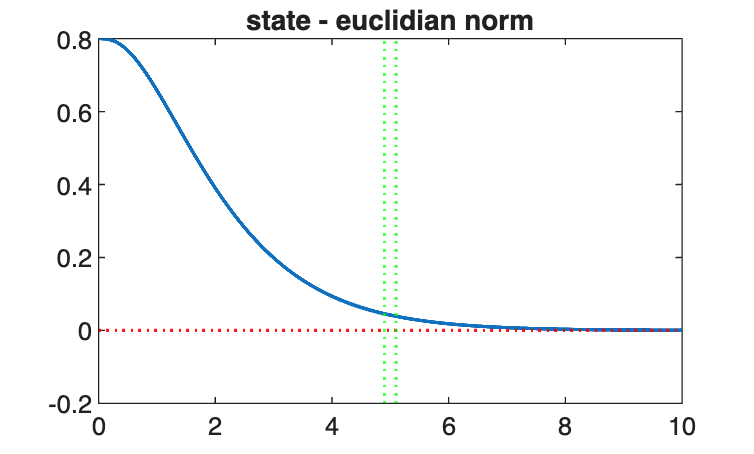

Tend = 8;
sys_x = ss(A,B,eye(2), 0);

out = sim("LQR_no_tracking.slx");

x = out.x;

figure
plot(x.time, sqrt(x.data(:,1).^2+x.data(:,2).^2), 'LineWidth',1.5);
title("state - euclidian norm")
yline(1e-5, ':r', 'LineWidth',1.2)
yline(-1e-5, ':r', 'LineWidth',1.2)
xline(5+0.02*5, ':g', 'LineWidth',1.2)
xline(5-0.02*5, ':g', 'LineWidth',1.2)

### Tuning

Since our requirement is not met, we must tune Q and R until we satisfy it

We can increase Q and R by one order of magnitude at a time

**Note: **the values of Q and R are my final choices.

**Note: **I didn't plot both state components, but if we do it, or we just analyze what happens to our states, we can clearly see that the "critical" state is the first one => we work just on that

R = 1.3; 
Q = [200, 0; 0 1];
Cq = chol(Q);
Mo = obsv(Ad,Cq);
rho_Mo = rank(Mo)

rho_Mo = 2

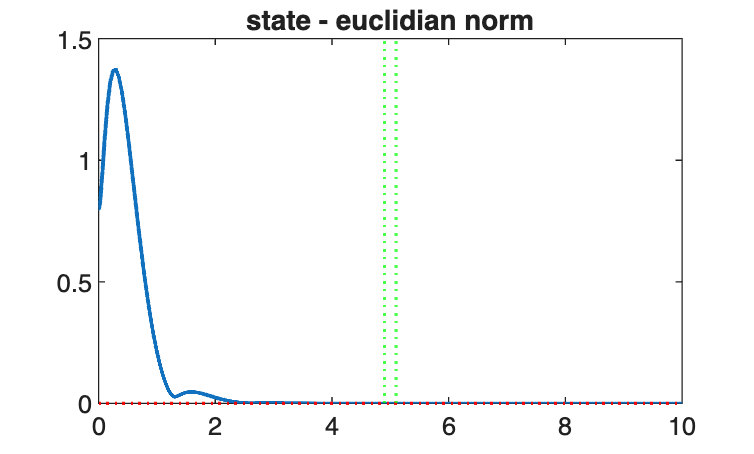

K = dlqr(Ad, Bd, Q, R);

clear out 

out = sim("LQR_no_tracking.slx");

x = out.x;

figure
plot(x.time, sqrt(x.data(:,1).^2+x.data(:,2).^2), 'LineWidth',1.5);
title("state - euclidian norm")
yline(1e-5, ':r', 'LineWidth',1.2)
yline(-1e-5, ':r', 'LineWidth',1.2)
xline(5+0.02*5, ':g', 'LineWidth',1.2)
xline(5-0.02*5, ':g', 'LineWidth',1.2)

## LQR with setpoint tracking

We can include to our LQR a reference input

The state feedback control architecture is modified as shown below:

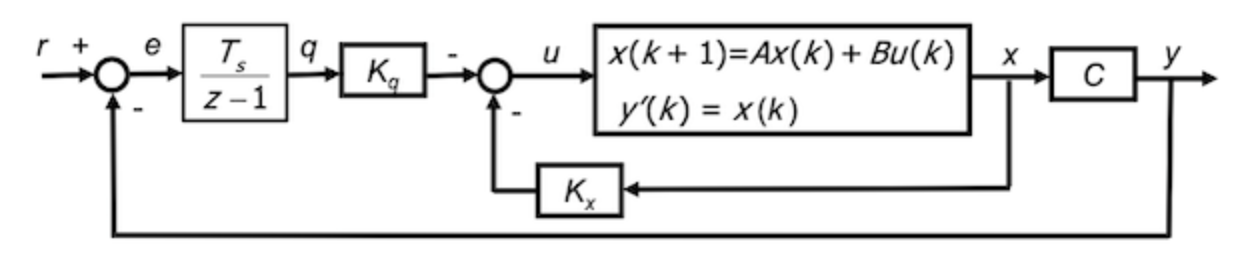

We obtain an augmented state...

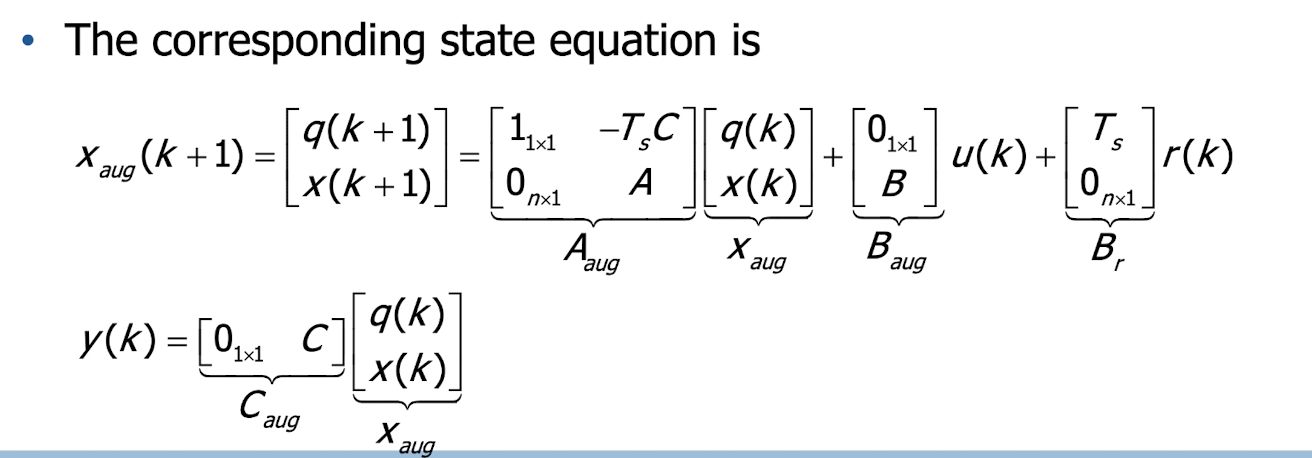

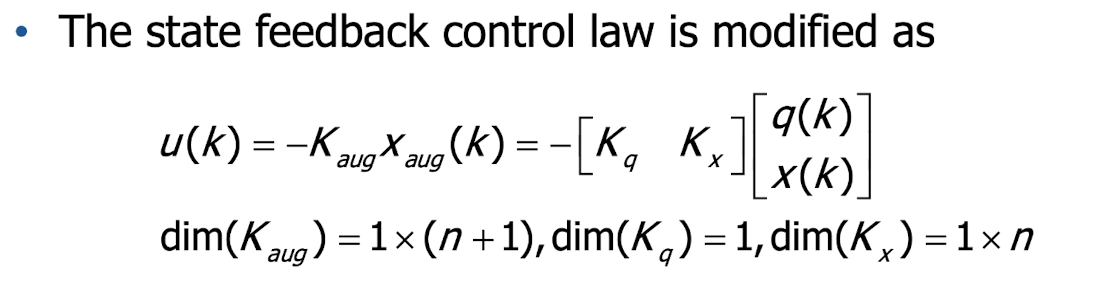

**It can be proved that the system guarantees zero steady state tracking error when the reference signal r is constant!!!!**

The design of the LQR control law with the integral state is performed using as system matrices A_aug and B_aug (the couple is reachable is (A,B) is reachable)

## Exercise 

#### Lab 4, problem 2

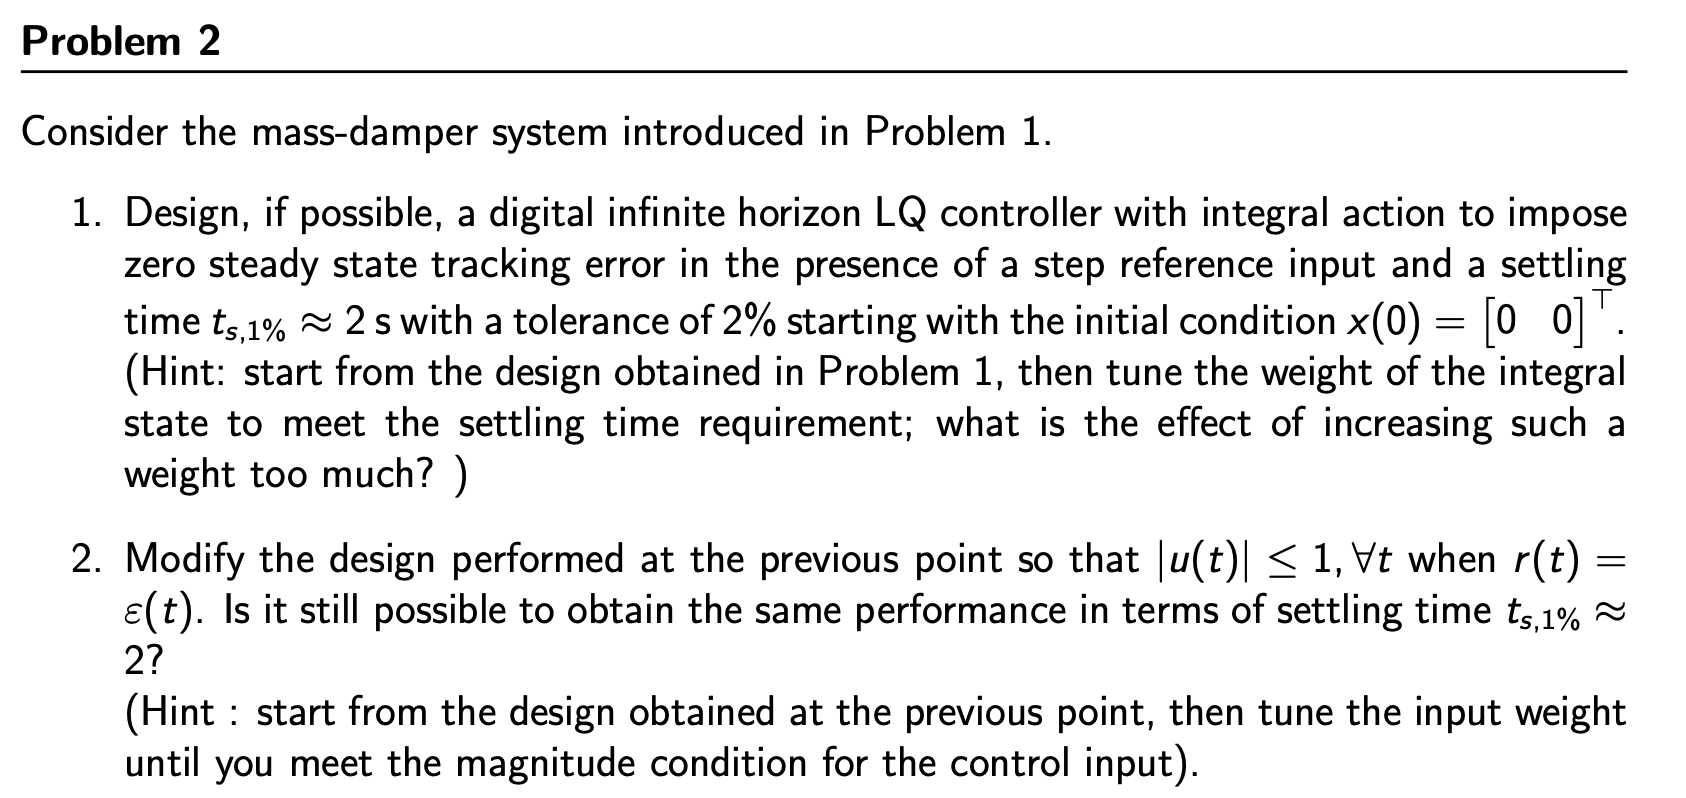

Firstly, we have to build our augmented state system

x0 = [0;0];
x0i = 0; % integrator initial condition
n = size(A,1);
p = size(B,2);
Aaug = [1 -Ts*Cd; zeros(n,1) Ad];
Baug = [0; Bd];
Caug = [0 Cd];

% let's define Q and R
Q = diag(ones(size(Aaug,1),1));
R = 1;

% we already know (from theory) that (Aaug Baug) is reachable since 
% (A,B) is reachable

% instead we have to check obsv

Cq = chol(Q);
Mo = obsv(Aaug, Cq);
rank_Mo = rank(Mo)

rank_Mo = 3


% we can now compute K
Kaug = dlqr(Aaug, Baug, Q, R);

% and then split it between Kq and Kx
Kq = Kaug(1);
Kx = Kaug(2:end);

#### Simulation

Tend = 8;
sys_x = ss(A,B,eye(2), 0);

out = sim("LQR_with_tracking.slx");

Model 'LQR_with_tracking.slx' does not exist.


y = out.y;
r = out.r;
e = out.e;

figure
plot(r.time, r.data, 'r--','LineWidth', 1.5);
hold on
plot(y.time, y.data, 'b','LineWidth',1.5);
title("response")
yline(1.01, ':r', 'LineWidth',1.2)
yline(0.99, ':r', 'LineWidth',1.2)
xline(2+0.02*2, ':g', 'LineWidth',1.2)
xline(2-0.02*2, ':g', 'LineWidth',1.2)

figure
plot(e.time, e.data, LineWidth=1.5);
title("error")

### Tuning

From the plot we clearly see that we need a faster response (ie we must increase Q values)

clear out

Q(1,1) = 4e4;
R = 1.4;

Kaug = dlqr(Aaug,Baug,Q,R);

Kq = Kaug(1);
Kx = Kaug(2:end);

out = sim("LQR_with_tracking.slx");

e = out.e;
y = out.y;
r = out.r;

figure
plot(r.time, r.data, 'r--','LineWidth', 1.5);
hold on
plot(y.time, y.data, 'b','LineWidth',1.5);
title("response")
yline(1.01, ':r', 'LineWidth',1.2)
yline(0.99, ':r', 'LineWidth',1.2)
xline(2+0.02*2, ':g', 'LineWidth',1.2)
xline(2-0.02*2, ':g', 'LineWidth',1.2)

figure
plot(e.time, e.data, LineWidth=1.5);
title("error")

Now settling time requirement is satisfied. We don't analyze the other questions